# RUN 3rd

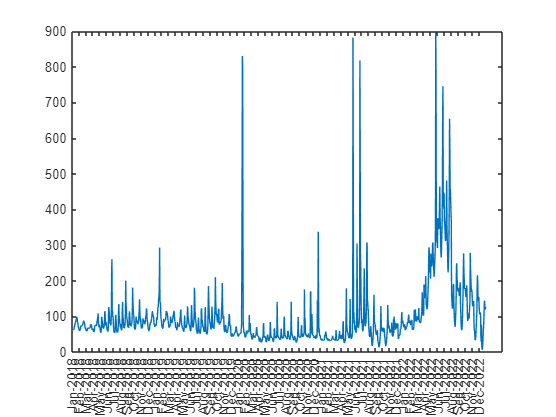

% average by hour in 1 month interval
k1 = year(PHSdata.SETTLEMENTDATE);
k2 = month(PHSdata.SETTLEMENTDATE);
k3 = hour(PHSdata.SETTLEMENTDATE);

meanPrice = [];
for slyear = y1:y2
    for slmonth = 1:12
        % index1 points out the segment belongs to slyear
        idx1 = k1==slyear & k2==slmonth;
        for slhour = 0:23
            % index2 points out the segment
            idx2 = k3==slhour;
            idx = idx1 & idx2;
            meanPrice = vertcat(meanPrice,mean(PHSdata.RRP(idx)));

            %     idx3 = PHSdata.PHSpump>0;
            %     idx = idx1 & idx2 & idx3;
            %     countPump(ii+1) = sum(idx);
            %
            %     idx3 = PHSdata.PHSgen>0;
            %     idx = idx1 & idx2 & idx3;
            %     countGen(ii+1) = sum(idx);
        end
        % kPump = countPump/sum(countPump);
        % kGen = countGen/sum(countGen);
    end
end

clf;
plot(meanPrice)
xticks(1:24:height(meanPrice));
xticklabels(datestr(datetime(2018,1,1):calmonths(1):datetime(2022,12,1),'mmm-yyyy'))

MonthHourlyMean = array2table(reshape(meanPrice,24,[]),"VariableNames",cellstr(datestr(datetime(y1,1,1):calmonths(1):datetime(y2,12,1),'mmm-yyyy')))

MonthHourlyMean = 24×60 table
    Jan-2018    Feb-2018    Mar-2018    Apr-2018    May-2018    Jun-2018    Jul-2018    Aug-2018    Sep-2018    Oct-2018    Nov-2018    Dec-2018    Jan-2019    Feb-2019    Mar-2019    Apr-2019    May-2019    Jun-2019    Jul-2019    Aug-2019    Sep-2019    Oct-2019    Nov-2019    Dec-2019    Jan-2020    Feb-2020    Mar-2020    Apr-2020    May-2020    Jun-2020    Jul-2020    Aug-2020    Sep-2020    O

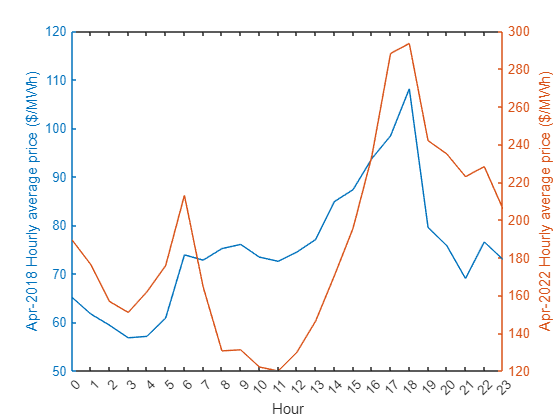

clf;
% hold on
yyaxis("left");
plot(MonthHourlyMean.("Apr-2018")); ylim([50 120]);
ylabel("Apr-2018 Hourly average price ($/MWh)")

yyaxis("right");
plot(MonthHourlyMean.("Apr-2022"))
ylabel("Apr-2022 Hourly average price ($/MWh)")

xlim([1 24])
xticks(1:24)
xticklabels(0:23)
xlabel("Hour")

monthH = max(reshape(meanPrice,24,[]))';
monthL = min(reshape(meanPrice,24,[]))';

k1 = year(calcPHSdaily.SETTLEMENTDATE);
k2 = month(calcPHSdaily.SETTLEMENTDATE);

sumGAUD = [];
sumPAUD = [];
sumGMWh = [];
sumPMWh = [];
for slyear = y1:y2
    for slmonth = 1:12
        idx1 = k1==slyear & k2==slmonth;
        sumGAUD = vertcat(sumGAUD,sum(calcPHSdaily.PHSgenAUD(idx1)));
        sumPAUD = vertcat(sumPAUD,sum(calcPHSdaily.PHSpumpAUD(idx1)));
        sumGMWh = vertcat(sumGMWh,sum(calcPHSdaily.PHSgenMWh(idx1)));
        sumPMWh = vertcat(sumPMWh,sum(calcPHSdaily.PHSpumpMWh(idx1)));
    end
end

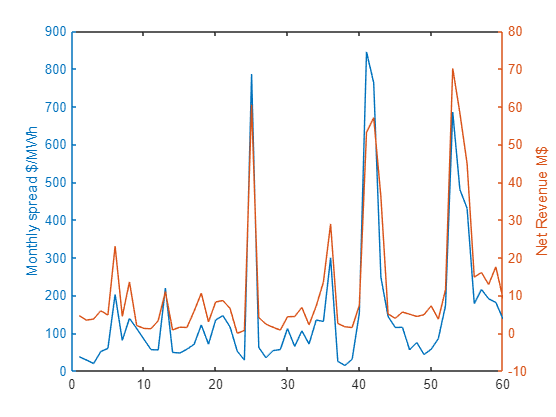

% clf;
% scatter(monthH,sumGAUD*1e-6)
% 
% clf;
% scatter(monthL,sumPAUD*1e-6)
% 
% clf;
% scatter(monthH-monthL,sumGAUD*1e-6-sumPAUD*1e-6)
% [rho,pval]=corr(monthH-monthL,sumGAUD*1e-6-sumPAUD*1e-6)

clf;
yyaxis("left");plot(monthH-monthL);ylabel('Monthly spread $/MWh')
yyaxis("right");plot(sumGAUD*1e-6-sumPAUD*1e-6);ylabel('Net Revenue M$')

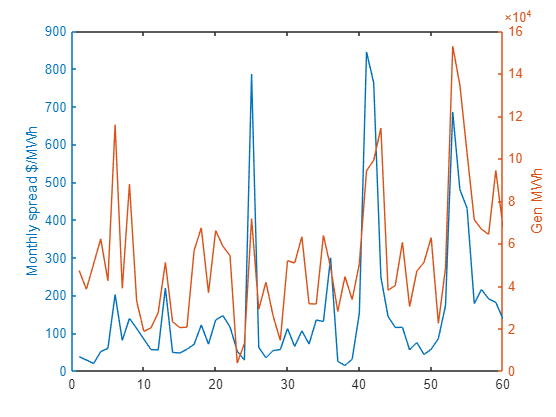

clf;
yyaxis("left");plot(monthH-monthL);ylabel('Monthly spread $/MWh')
yyaxis("right");plot(sumGMWh);ylabel('Gen MWh')